# **Control Data**

clear
clc
clf
rng default

## Load Data

pi = load("picontrol_run2.mat");

# **PI Control**

## PI Data Extraction

t = pi.picontrol.get("eTape1").Values.Time;
h1 = pi.picontrol.get("eTape1").Values.Data;
h2 = pi.picontrol.get("eTape2").Values.Data;
v1 = pi.picontrol.get("v1").Values.Data;
v2 = pi.picontrol.get("v2").Values.Data;
SP1 = pi.picontrol.get("SP1").Values.Data;
SP2 = pi.picontrol.get("SP2").Values.Data;
e1 = pi.picontrol.get("error1").Values.Data;
e2 = pi.picontrol.get("error2").Values.Data;

## Total Plot

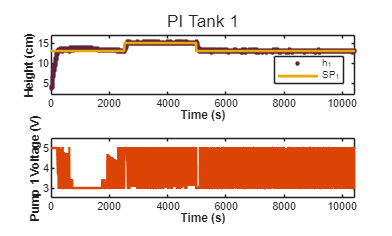

fig1 = figure(1);
f1 = tiledlayout(fig1, 2, 1);
title(f1, "PI Tank 1")

nexttile
plot(t, h1, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t, SP1, "LineWidth", 2, "Color", "#eba900")
legend("h_1", "SP_1", "Location", "southeast")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
xlim([0 t(end)])
ylim([2 17])
hold off

nexttile
plot(t, v1, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 1 Voltage (V)", "FontWeight", "bold")
xlim([0 t(end)])
ylim([2.5 5.5])

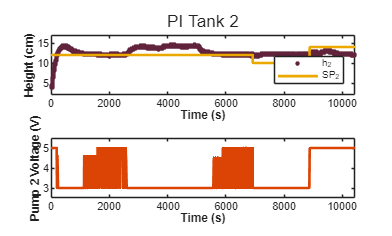


fig2 = figure(2);
f2 = tiledlayout(fig2, 2, 1);
title(f2, "PI Tank 2")

nexttile
plot(t, h2, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t, SP2, "LineWidth", 2, "Color", "#eba900")
legend("h_2", "SP_2", "Location", "southeast")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
xlim([0 t(end)])
ylim([2 17])
hold off

nexttile
plot(t, v2, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 2 Voltage (V)", "FontWeight", "bold")
xlim([0 t(end)])
ylim([2.5 5.5])

## PI Before Step

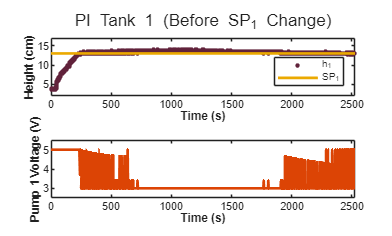

SP1_step = 15;
SP1_idx = find(SP1 == SP1_step, 1, "first") - 1;

fig3 = figure(3);
f3 = tiledlayout(fig3, 2, 1);
title(f3, "PI Tank 1 (Before SP_1 Change)")

nexttile
plot(t(1:SP1_idx), h1(1:SP1_idx), "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t(1:SP1_idx), SP1(1:SP1_idx), "LineWidth", 2, "Color", "#eba900")
legend("h_1", "SP_1", "Location", "southeast")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
xlim([0 t(SP1_idx)])
ylim([2 17])
hold off

nexttile
plot(t(1:SP1_idx), v1(1:SP1_idx), "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 1 Voltage (V)", "FontWeight", "bold")
ylim([2.5 5.5])
xlim([0 t(SP1_idx)])

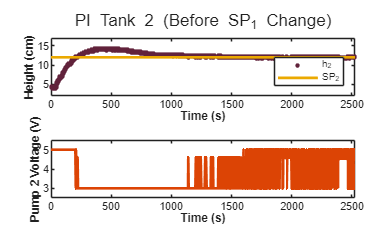


fig4 = figure(4);
f4 = tiledlayout(fig4, 2, 1);
title(f4, "PI Tank 2 (Before SP_1 Change)")

nexttile
plot(t(1:SP1_idx), h2(1:SP1_idx), "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t(1:SP1_idx), SP2(1:SP1_idx), "LineWidth", 2, "Color", "#eba900")
legend("h_2", "SP_2", "Location", "southeast")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
xlim([0 t(SP1_idx)])
ylim([2 17])
hold off

nexttile
plot(t(1:SP1_idx), v2(1:SP1_idx), "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 2 Voltage (V)", "FontWeight", "bold")
ylim([2.5 5.5])
xlim([0 t(SP1_idx)])

## PI After Step 1

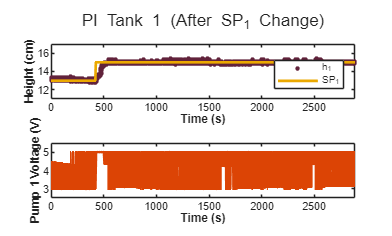

SP1_idx_2 = find(SP1 == SP1_step, 1, "last") - 1;
t_dead = find(t == 2100);
t_1 = t(t_dead:SP1_idx_2) - t(t_dead);
h1_1 = h1(t_dead:SP1_idx_2);
h2_1 = h2(t_dead:SP1_idx_2);
SP1_1 = SP1(t_dead:SP1_idx_2);
SP2_1 = SP2(t_dead:SP1_idx_2);
v1_1 = v1(t_dead:SP1_idx_2);
v2_1 = v2(t_dead:SP1_idx_2);

fig5 = figure(5);
f5 = tiledlayout(fig5, 2, 1);
title(f5, "PI Tank 1 (After SP_1 Change)")

nexttile
plot(t_1, h1_1, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_1, SP1_1, "LineWidth", 2, "Color", "#eba900")
legend("h_1", "SP_1", "Location", "southeast")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
xlim([0 t_1(end)])
ylim([11 17])
hold off

nexttile
plot(t_1, v1_1, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 1 Voltage (V)", "FontWeight", "bold")
xlim([0 t_1(end)])
ylim([2.5 5.5])
hold off

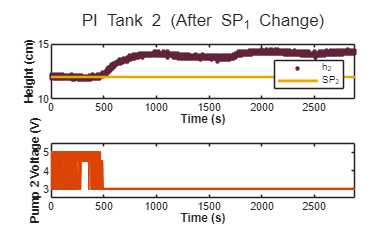


fig6 = figure(6);
f6 = tiledlayout(fig6, 2, 1);
title(f6, "PI Tank 2 (After SP_1 Change)")

nexttile
plot(t_1, h2_1, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_1, SP2_1, "LineWidth", 2, "Color", "#eba900")
legend("h_2", "SP_2", "Location", "southeast")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
xlim([0 t_1(end)])
ylim([10 15])
hold off

nexttile
plot(t_1, v2_1, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 2 Voltage (V)", "FontWeight", "bold")
xlim([0 t_1(end)])
ylim([2.5 5.5])

## PI After Step 2

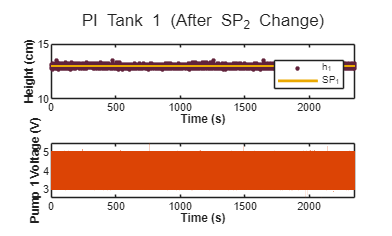

SP2_step = 10;
SP2_idx = find(SP2 == SP2_step, 1, "first") - 1;
SP2_idx_end = find(SP2 == SP2_step, 1, "last") - 1;
t_2 = t((SP2_idx - 4000):SP2_idx_end) - t(SP2_idx - 4000);
h1_2 = h1((SP2_idx - 4000):SP2_idx_end);
h2_2 = h2((SP2_idx - 4000):SP2_idx_end);
v1_2 = v1((SP2_idx - 4000):SP2_idx_end);
v2_2 = v2((SP2_idx - 4000):SP2_idx_end);
SP1_2 = SP1((SP2_idx - 4000):SP2_idx_end);
SP2_2 = SP2((SP2_idx - 4000):SP2_idx_end);

fig7 = figure(7);
f7 = tiledlayout(fig7, 2, 1);
title(f7, "PI Tank 1 (After SP_2 Change)")

nexttile
plot(t_2, h1_2, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_2, SP1_2, "LineWidth", 2, "Color", "#eba900")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend("h_1", "SP_1", "Location", "southeast")
xlim([0 t_2(end)])
ylim([10 15])
hold off

nexttile
plot(t_2, v1_2, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 1 Voltage (V)", "FontWeight", "bold")
xlim([0 t_2(end)])
ylim([2.5 5.5])

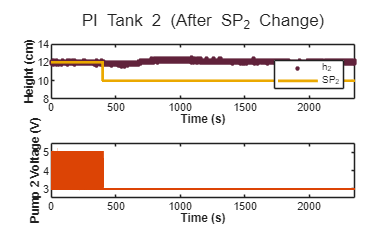



fig8 = figure(8);
f8 = tiledlayout(fig8, 2, 1);
title(f8, "PI Tank 2 (After SP_2 Change)")

nexttile
plot(t_2, h2_2, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_2, SP2_2, "LineWidth", 2, "Color", "#eba900")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
legend("h_2", "SP_2", "Location", "southeast")
xlim([0 t_2(end)])
ylim([8 14])
hold off

nexttile
plot(t_2, v2_2, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 2 Voltage (V)", "FontWeight", "bold")
xlim([0 t_2(end)])
ylim([2.5 5.5])

## Metrics

ITAE determined once tank has settled (only over a small time frame)

e(t) = SP(t) - CV(t)

% error = e(t)/SP(t)

variable format = variable1/2_SP1/SP2_name (e.g. e1_1_percent)

+- 2% band taken from Liptak

settling time of 30 seconds

% ITAE after SP1 change
t_1_ITAE = t((find(SP1 == SP1_step, 1, "first")):SP1_idx_2) - t(find(SP1 == SP1_step, 1, "first"));
e1_1 = e1((find(SP1 == SP1_step, 1, "first")):SP1_idx_2);
e2_1 = e2((find(SP1 == SP1_step, 1, "first")):SP1_idx_2);
SP1_1 = SP1((find(SP1 == SP1_step, 1, "first")):SP1_idx_2);
SP2_1 = SP2((find(SP1 == SP1_step, 1, "first")):SP1_idx_2);
% e1_1_percent = (e1_1./SP1_1).*100;
% e2_1_percent = (e2_1./SP2_1).*100;

% plot(t_1_ITAE, e2(25256:SP1_idx_2))
% plot(t_1_ITAE, h2_pmm((find(SP1 == SP1_step, 1, "first")):SP1_idx_2), t_1_ITAE, SP2_1)

% settling window
tolerance = 2/100;
ub1 = tolerance*SP1_1(1); % upper bound
lb1 = -tolerance*SP1_1(1); % lower bound
st = 150; % settling time
dt = 0.1; % sample time
st_samples = st/dt; % number of samples (i.e. rows in matrix)
e1_1_bounds = (e1_1 >= lb1) & (e1_1 <= ub1); % true or false matrix (1 or 0) to determine 30 s of settling

e1_1_settleidx = [];
for i = 1:(length(e1_1_bounds) - st_samples)
    if all(e1_1_bounds(i:i + st_samples))
        e1_1_settleidx = i; % i is the index where the level has settled and the 150 seconds are within the bounds
        break;
    end
end

% settling time for SP1 change
t1_1_settle = t_1_ITAE(e1_1_settleidx)

t1_1_settle = 183.1000


% time windows for calculating ITAE
window = 200;
idx1 = find(t_1_ITAE <= window);

% ITAE for SP1 change
ITAE1_1 = trapz(t_1_ITAE(idx1), t_1_ITAE(idx1).*abs(e1_1(idx1)))

ITAE1_1 = 3.2228e+03

ITAE2_1 = trapz(t_1_ITAE(idx1), t_1_ITAE(idx1).*abs(e2_1(idx1)))

ITAE2_1 = 1.5396e+04


% ISE for SP1 change
ISE1_1 = trapz(t_1_ITAE(idx1), (e1_1(idx1)).^2)

ISE1_1 = 117.8977

ISE2_1 = trapz(t_1_ITAE(idx1), (e2_1(idx1)).^2)

ISE2_1 = 92.2357


% IAE for SP1 change
IAE1_1 = trapz(t_1_ITAE(idx1), abs(e1_1(idx1)))

IAE1_1 = 92.1753

IAE2_1 = trapz(t_1_ITAE(idx1), abs(e2_1(idx1)))

IAE2_1 = 107.8440

% ITAE after SP2 change
t_2_ITAE = t((SP2_idx + 1):(SP2_idx_end)) - t((SP2_idx + 1));
e1_2 = e1((SP2_idx + 1):(SP2_idx_end));
e2_2 = e2((SP2_idx + 1):(SP2_idx_end));
SP1_2 = SP1((SP2_idx + 1):(SP2_idx_end));
SP2_2 = SP2((SP2_idx + 1):(SP2_idx_end));

% settling window
tolerance = 2/100;
ub2 = tolerance*SP2_1(1); % upper bound
lb2 = -tolerance*SP2_1(1); % lower bound
st = 150; % settling time
dt = 0.1; % sample time
st_samples = st/dt; % number of samples (i.e. rows in matrix)
e2_2_bounds = (e2_2 >= lb2) & (e2_2 <= ub2); % true or false matrix (1 or 0) to determine 30 s of settling

e2_2_settleidx = [];
for j = 1:(length(e2_2_bounds) - st_samples)
    if all(e2_2_bounds(j:j + st_samples))
        e2_2_settleidx = j;
        break;
    end
end

% ITAE for SP2 change

% time window for calculating ITAE
idx2 = find(t_2_ITAE <= window);

% ITAE for SP1 change
ITAE1_2 = trapz(t_2_ITAE(idx2), t_2_ITAE(idx2).*abs(e1_2(idx2)))

ITAE1_2 = 1.1872e+03

ITAE2_2 = trapz(t_2_ITAE(idx2), t_2_ITAE(idx2).*abs(e2_2(idx2)))

ITAE2_2 = 3.7293e+04


% ISE for SP1 change
ISE1_2 = trapz(t_2_ITAE(idx2), (e1_2(idx2)).^2)

ISE1_2 = 1.8111

ISE2_2 = trapz(t_2_ITAE(idx2), (e2_2(idx2)).^2)

ISE2_2 = 705.9581


% IAE for SP1 change
IAE1_2 = trapz(t_2_ITAE(idx2), abs(e1_2(idx2)))

IAE1_2 = 12.2502

IAE2_2 = trapz(t_2_ITAE(idx2), abs(e2_2(idx2)))

IAE2_2 = 375.5113

## Inconsistencies

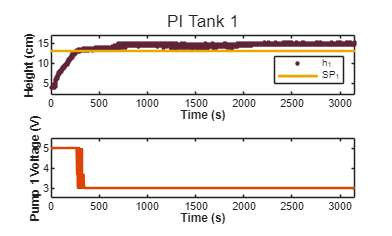

inc = load("picontrol_run1.mat");

t_inc = inc.picontrol.get("eTape1").Values.Time;
h1_inc = inc.picontrol.get("eTape1").Values.Data;
h2_inc = inc.picontrol.get("eTape2").Values.Data;
v1_inc = inc.picontrol.get("v1").Values.Data;
v2_inc = inc.picontrol.get("v2").Values.Data;
SP1_inc = inc.picontrol.get("SP1").Values.Data;
SP2_inc = inc.picontrol.get("SP2").Values.Data;

fig9 = figure(9);
f9 = tiledlayout(fig9, 2, 1);
title(f9, "PI Tank 1")

nexttile
plot(t_inc, h1_inc, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_inc, SP1_inc, "LineWidth", 2, "Color", "#eba900")
legend("h_1", "SP_1", "Location", "southeast")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
xlim([0 t_inc(end)])
ylim([2 17])
hold off

nexttile
plot(t_inc, v1_inc, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 1 Voltage (V)", "FontWeight", "bold")
xlim([0 t_inc(end)])
ylim([2.5 5.5])

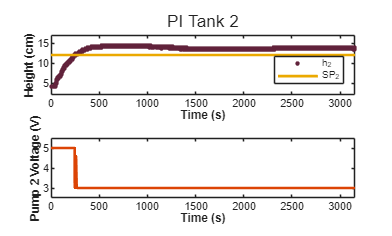


fig10 = figure(10);
f10 = tiledlayout(fig10, 2, 1);
title(f10, "PI Tank 2")

nexttile
plot(t_inc, h2_inc, "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t_inc, SP2_inc, "LineWidth", 2, "Color", "#eba900")
legend("h_2", "SP_2", "Location", "southeast")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
xlim([0 t_inc(end)])
ylim([2 17])
hold off

nexttile
plot(t_inc, v2_inc, "LineWidth", 2, "Color", "#dc4405")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("Pump 2 Voltage (V)", "FontWeight", "bold")
xlim([0 t_inc(end)])
ylim([2.5 5.5])

## Checking Data

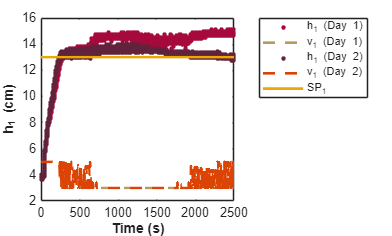

fig11 = figure(11);
title("PI Tank 1 - h_1 vs. v_1")
plot(t_inc(1:SP1_idx), h1_inc(1:SP1_idx), "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#A60A3D")
hold on
plot(t_inc(1:SP1_idx), v1_inc(1:SP1_idx), "LineWidth", 2, "Color", "#b79962", "LineStyle", "--")
hold on
plot(t(1:SP1_idx), h1(1:SP1_idx),  "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t(1:SP1_idx), v1(1:SP1_idx), "LineWidth", 2, "Color", "#dc4405", "LineStyle", "--")
hold on
plot(t(1:SP1_idx), SP1(1:SP1_idx), "LineWidth", 2, "Color", "#eba900")

legend("h_1 (Day 1)", "v_1 (Day 1)", "h_1 (Day 2)", "v_1 (Day 2)", "SP_1", "Location", "bestoutside")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("h_1 (cm)", "FontWeight", "bold")
xlim([0 2500])
% ylim([3 17])
hold off

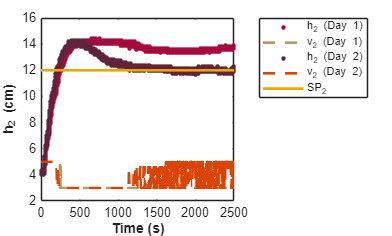



fig12 = figure(12);
title("PI Tank 2 - h_2 vs. v_2")
plot(t_inc(1:SP1_idx), h2_inc(1:SP1_idx), "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#A60A3D")
hold on
plot(t_inc(1:SP1_idx), v2_inc(1:SP1_idx), "LineWidth", 2, "Color", "#b79962", "LineStyle", "--")
hold on
plot(t(1:SP1_idx), h2(1:SP1_idx),  "Marker", " .", "MarkerSize", 10, "LineStyle", "none", "MarkerEdgeColor", "#61223b")
hold on
plot(t(1:SP1_idx), v2(1:SP1_idx), "LineWidth", 2, "Color", "#dc4405", "LineStyle", "--")
hold on
plot(t(1:SP1_idx), SP2(1:SP1_idx), "LineWidth", 2, "Color", "#eba900")

legend("h_2 (Day 1)", "v_2 (Day 1)", "h_2 (Day 2)", "v_2 (Day 2)", "SP_2", "Location", "bestoutside")
xlabel("Time (s)", "FontWeight", "bold")
ylabel("h_2 (cm)", "FontWeight", "bold")
xlim([0 2500])
% ylim([3 17])
hold off